# Laboratorio 8 Control Discreto - Discreto

k=0.7;
tao=1;

tm=4*tao/50

tm = 0.0800


plantaContinua=tf(k,[tao 1])

plantaContinua =
 
   0.7
  -----
  s + 1
 
Continuous-time transfer function.



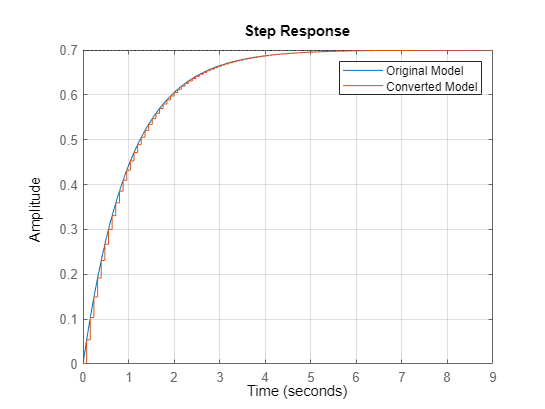

% Convert model from continuous to discrete time
plantaDis = c2d(plantaContinua,0.08);

% Visualize the results
stepplot(plantaContinua,plantaDis);
legend('Original Model','Converted Model');
grid on;

plantaDis

plantaDis =
 
   0.05382
  ----------
  z - 0.9231
 
Sample time: 0.08 seconds
Discrete-time transfer function.



[B,A]=tfdata(plantaDis,'v')

B =          0    0.0538


A =     1.0000   -0.9231



syms r0 r1 r2 z

B=poly2sym(B,z)

$$B = \frac{3878035770157129}{72057594037927936}$$

A=poly2sym(A,z)

$$A = z-\frac{8314692867212933}{9007199254740992}$$

R=r0*z^2+r1*z+r2;
S=collect((z-1)*(z-1),z)

$$S = z^{2}-2\,z+1$$


% polinomio deseado

zd=0.9;
tsd=4;
wnd=4/(zd*tsd)

wnd = 1.1111

p1=-2*exp(-zd*wnd*tm)...
    *cos(wnd*tm*sqrt(1-zd^2));
p2= exp(-2*zd*wnd*tm);

poldes=vpa(collect((z^2+p1*z+p2)*(z-0.1),z),4)

$$poldes = z^{3}-1.945\,z^{2}+1.037\,z-0.08521$$


polcarac=vpa(collect(B*R+A*S,z),4)

$$polcarac = z^{3}+\left(0.05382\,r_{0}-2.923\right)\,z^{2}+\left(0.05382\,r_{1}+2.846\right)\,z+0.05382\,r_{2}-0.9231$$


sol=vpa(coeffs(polcarac,z)==coeffs(poldes,z),4)

$$sol = \left(\begin{array}{cccc} 0.05382\,r_{2}-0.9231=-0.08521 & 0.05382\,r_{1}+2.846=1.037 & 0.05382\,r_{0}-2.923=-1.945 & 1.0=1.0 \end{array}\right)$$

sol=solve(sol)

sol = struct with fields:
    r0: 18.177174181746555830359406373874
    r1: -33.624167604782488385329637132348
    r2: 15.569015706771787206419893029689



r0=double(sol.r0)

r0 = 18.1772

r1=double(sol.r1)

r1 = -33.6242

r2=double(sol.r2)

r2 = 15.5690


[B,A]=tfdata(plantaDis,'v') 

B =          0    0.0538


A =     1.0000   -0.9231
